# Forward Difference Method

## En liten test

Tester først mot eksempelet i boka:

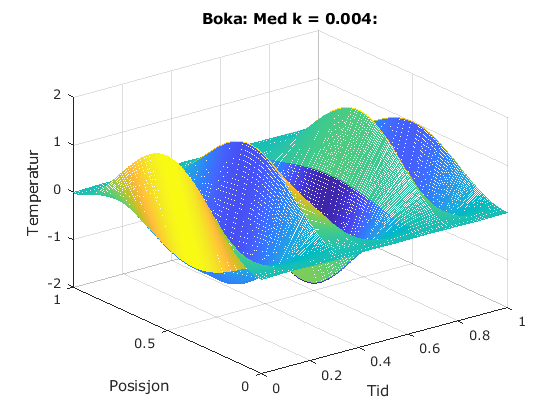

D = 1; M = 10; N = 250;
f = @(x) sin(1*pi*x).^2;
l = @(t) 0*t;
r = @(t) 0*t;
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("Boka: Med k = 0.004:");

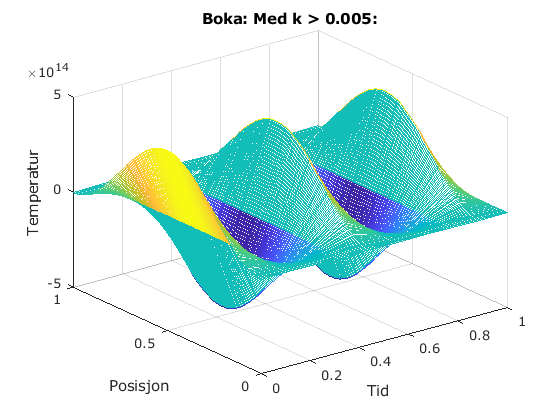

heatfdm(0, 1, 1, M, (1/0.005), D, f, l, r);
title("Boka: Med k > 0.005:");

## CP1 – fellestrekk

Skal løse $u_t = 2u_{xx}
$ i begge deloppgavene – altså er $D=2
$.

D = 2;

Beregningene skjer med h = 0.1 og k = 0.002, altså M = 10 og N = 500.

M = 1/0.1;
N = 1/0.002;

Vi skal sammenligne med k > 0.003:

N2 = round(1/0.003) - 1;

## CP1a


$$u(x,0) = 2\cosh x \text{ for } 0 \le  x \le  1\\
u(0,t) = 2e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = (e^2 + 1)e^{2t-1} \text{ for } 0 \le  t \le  1$$


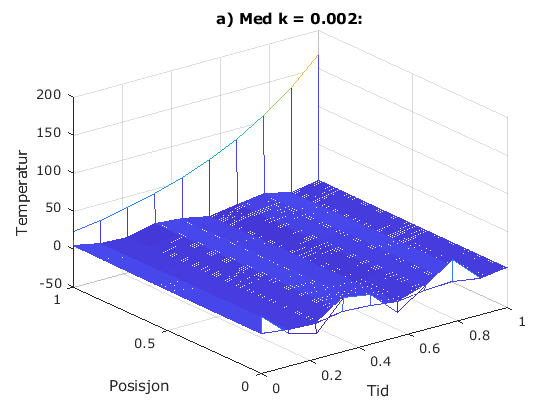

f = @(x) 2*cosh(x);
l = @(t) 2*exp(2*t);
r = @(t) (exp(2)+1)*exp(2*t+1);
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("a) Med k = 0.002:");

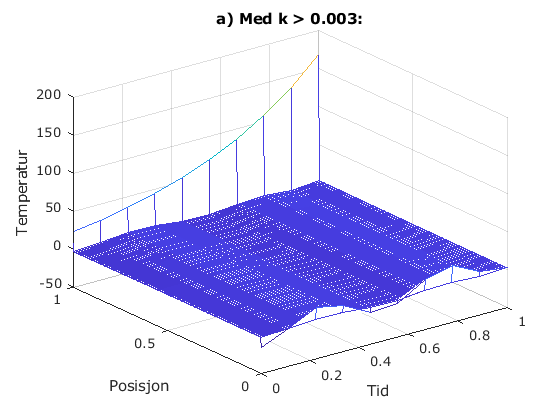

heatfdm(0, 1, 1, M, N2, D, f, l, r);
title("a) Med k > 0.003:");

## CP1b


$$u(x,0) = e^x \text{ for } 0 \le  x \le  1\\
u(0,t) = e^{2t} \text{ for } 0 \le  t \le  1\\
u(1,t) = e^{2t-1} \text{ for } 0 \le  t \le  1$$


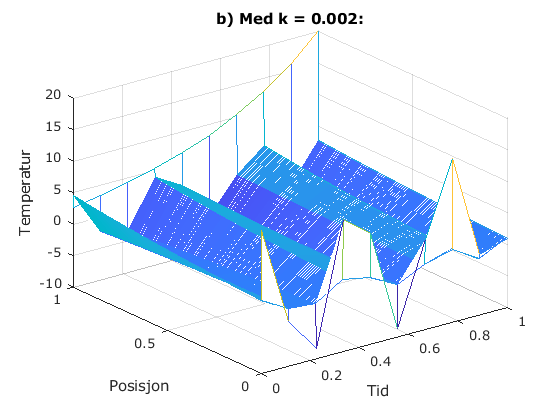

f = @(x) exp(x);
l = @(t) exp(2*t);
r = @(t) exp(2*t+1);
heatfdm(0, 1, 1, M, N, D, f, l, r);
title("b) Med k = 0.002:");

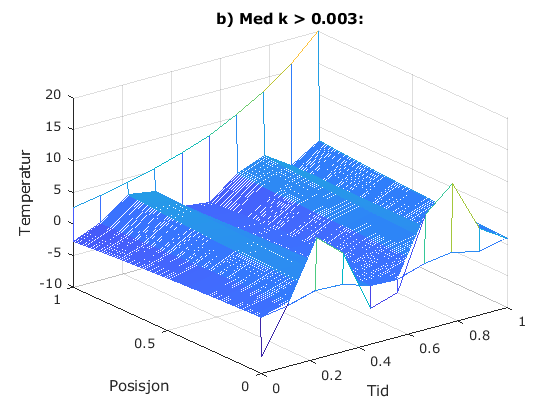

heatfdm(0, 1, 1, M, N2, D, f, l, r);
title("b) Med k > 0.003:");

Funksjonene:

function w=heatfdm(a, b, T, M, N, D, f, l, r)
%HEATBDM Forward Difference Method for the heat equation
%   Løser  u_t = D u_xx  numerisk
%   a og b er grensebetingelsene u(a,t)=l(t) og u(b,t)=r(t)
%   T utgjør høyre grense i tidsintervallet [0,T]
%   f(x) er initialbetingelsen for u(x,0)
%   D er diffusjonskoeffisienten (i den originale likningen)
%   M og N er antall samplinger langs x- og t-aksen
%   NB: f, l og r er funksjoner

    % Beregner steglengder og sigma
    h = (b-a)/M;
    k = T/N;
    sigma = D*k / (h*h);
    m = M-1;
    
    % Setter opp aksene
    x = linspace(a,b,M)';
    t = linspace(0,T,N)';
    
    % Lager diagonalmatrisen A
    e = ones(m, 1);
    A = spdiags([sigma*e, (1-2*sigma)*e, sigma*e], [-1,0,1], m, m);
    % er fortegnene eneste forskjell?
    
    w = zeros(M,N);
    w(:,1) = l(x);
    w(M,:) = f(t');
    for i = 1:N
        s = sigma*[w(1,i) zeros(1,m-2) w(M,i)]';
        w(1:m,i) = A\(w(1:m,i) + s);
    end
    w(:,N) = r(x);
    
    [X,T] = meshgrid(x,t);
    mesh(X,T,w')
    xlabel('Tid')
    ylabel('Posisjon')
    zlabel('Temperatur')
end